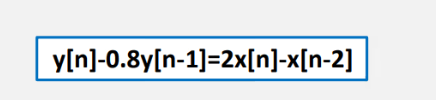

# freqz

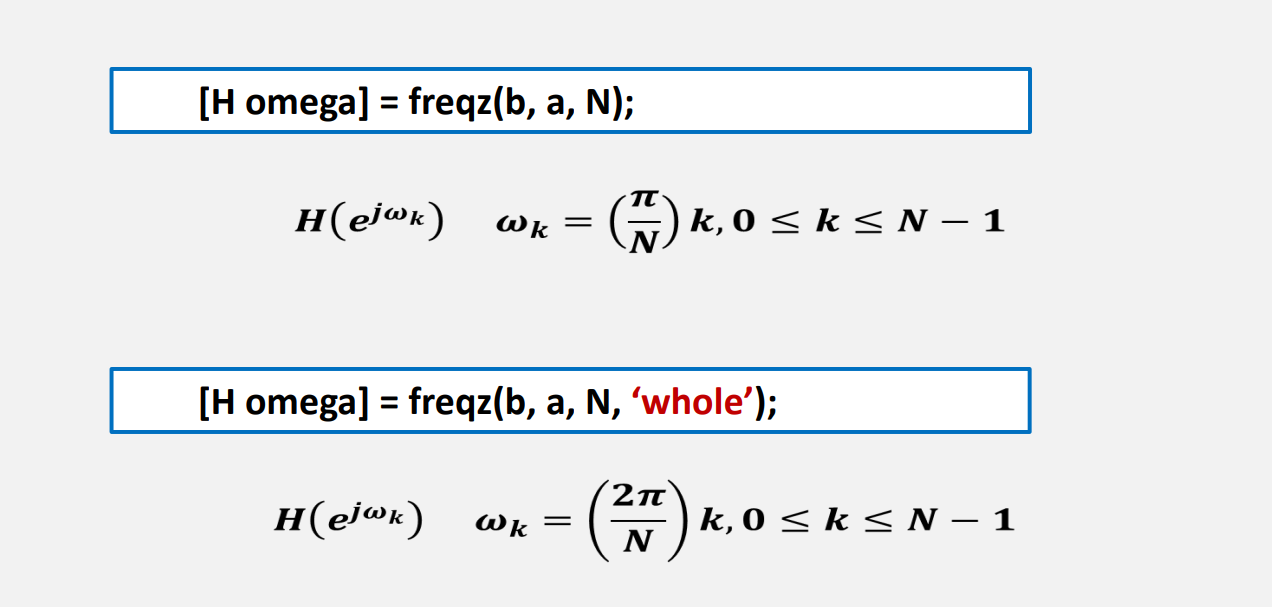

有人问freqz是求什么的，就说 已知了一个差分表达式 de system. Get the engin function

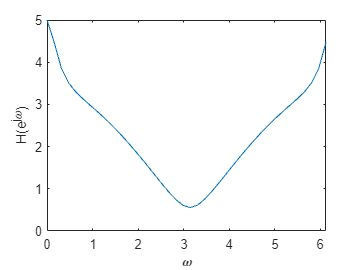

A = [1, -0.8];
B = [2, 0, -1];
[H, w] = freqz(B,A,40,'whole');
plot(w, abs(H));
xlabel('\omega');
ylabel('H(e^{j\omega})');

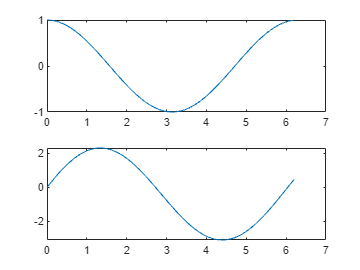

b = 3;
a = [1 0.3];
t = 0:0.1:2*pi;
x = cos(t);
y = lsim(b, a, x, t);
fprac3_2 = figure;
figure(fprac3_2);
subplot(2,1,1);
plot(t, x);
subplot(2,1,2);
plot(t, y);

# fft ifft

求取一个离散序列的傅里叶序列

a = (1/N)fft(x)

x = ifft(a)*N

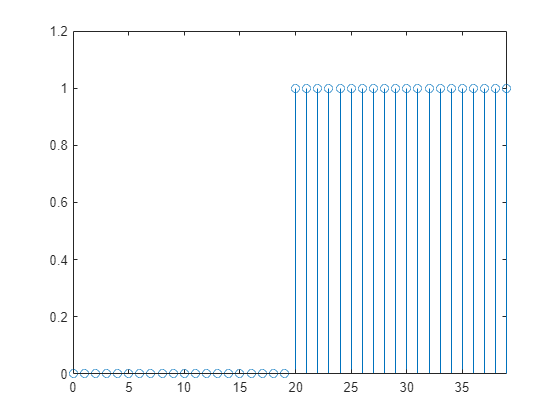

x=[zeros(1,20) ones(1,20)];
stem(0:39, x);
xlim([0 39]);
ylim([0 1.2]);

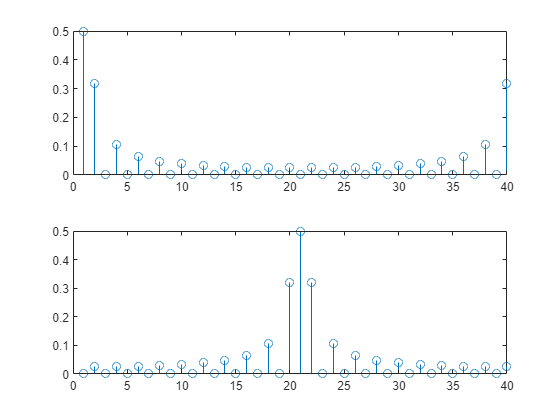


A = fft(x) / length(x);
figure(1)
subplot(2,1,1),stem(abs(A));
subplot(2,1,2),stem(abs(fftshift(A)));

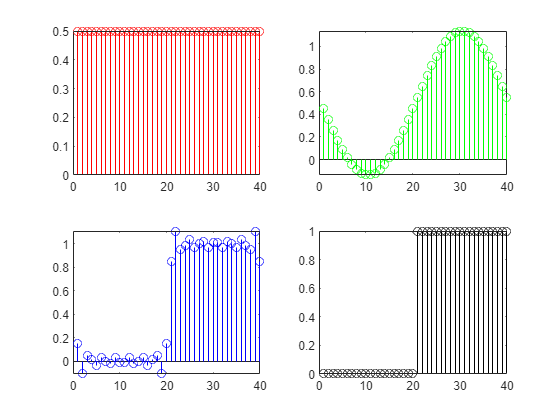


A1 = [A(1) zeros(1,39)];
A2 = [A(1) A(2) zeros(1,37) A(40)];
A3 = [A(1) A(2:15) zeros(1,11) A(27:40)];
figure(2)
subplot(2,2,1), stem(1:40,ifft(A1)*40, 'r');
subplot(2,2,2), stem(1:40,ifft(A2)*40, 'g');
subplot(2,2,3), stem(1:40,ifft(A3)*40, 'b');
subplot(2,2,4), stem(1:40,x, 'k');